clear all;clc
Original_Uint = imread('dogOriginal.bmp');
Noise_Uint = imread('dogDistorted.bmp');

Original = double(Original_Uint);
Noise = double(Noise_Uint);

mse_Original_Noise = immse(Original, Noise)% 原图和噪声

mse_Original_Noise = 4.6292e+03

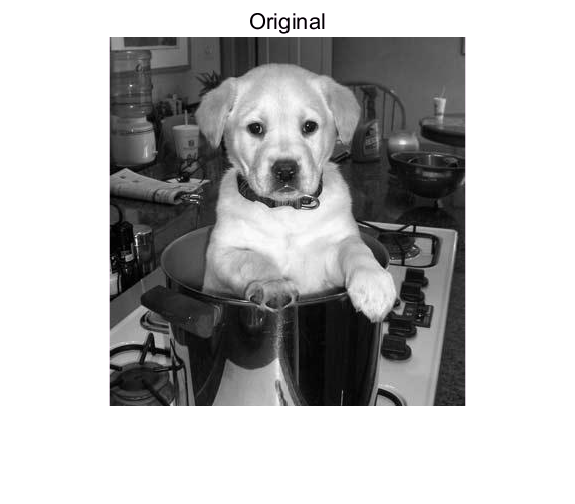


[M, N] = size(Noise);

imshow(mat2gray(Original)); title('Original');

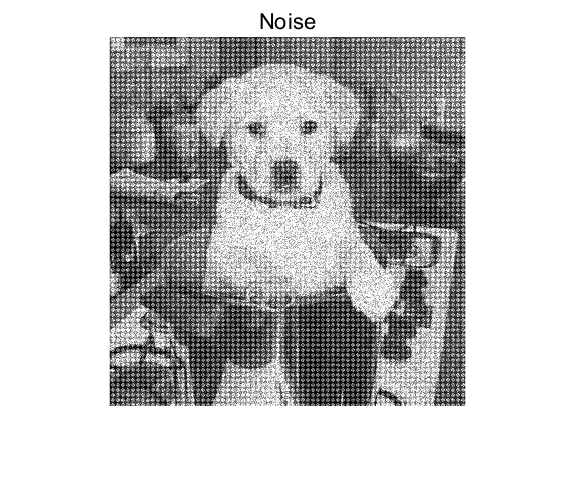

imshow(mat2gray(Noise)); title('Noise');

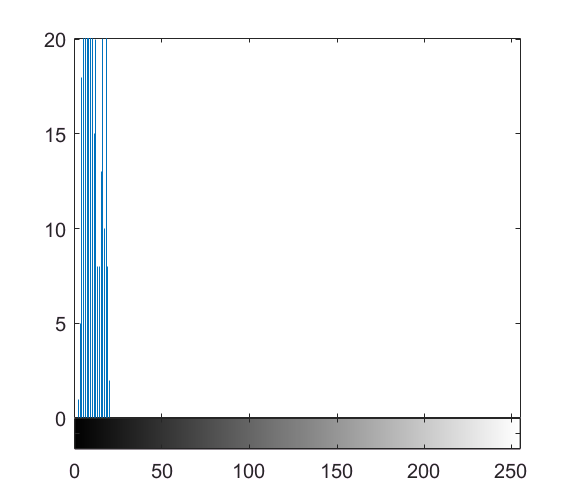


Original_loc=Original_Uint(300:320,200:220);
Noise_loc=Noise_Uint(300:320,200:220);
%imshow(Original_loc);
%imshow(Noise_loc);
imhist(Original_loc);

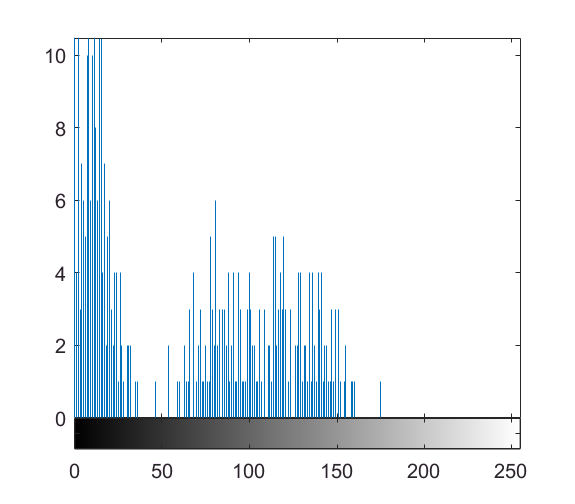

imhist(Noise_loc);

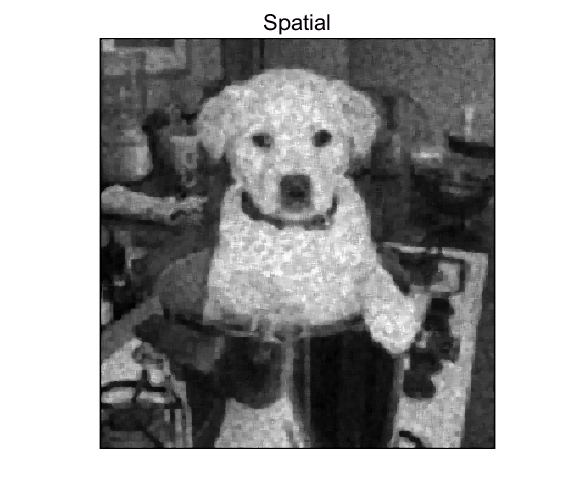

%%% 空域平滑 %%%
Filter = Noise;
%H = fspecial('average', 5);
%Filter = filter2(H, Filter);
%Filter = medfilt2(Filter, [5, 5]);
%Filter = TwostaticFilter(Filter,8,[5 5]);
Filter = ordfilt2(Filter,8,ones(5,5));
%Filter = ordfilt2(Filter,13,ones(6,6));

imshow(mat2gray(Filter)); title('Spatial');

imwrite(mat2gray(Filter),'DogSpatial.bmp');
mse_Original_Spatial = immse(Original, Filter)% 原图和空域

mse_Original_Spatial = 361.4758

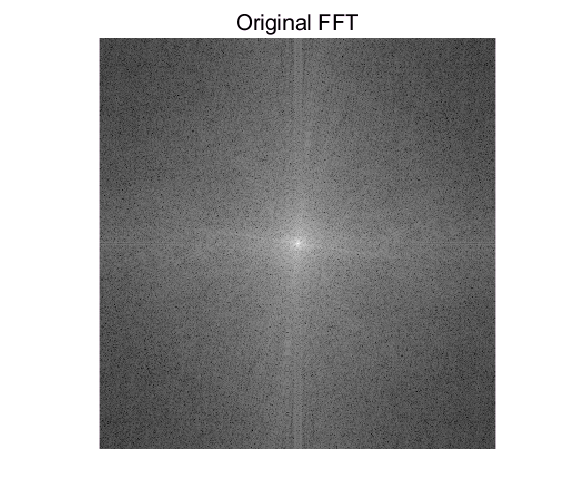

%%% 空域平滑 %%%

%%% FFT %%%
Original_fft = fft2(double(Original));
Original_fft_shift = fftshift(Original_fft);
Noise_fft = fft2(double(Noise));
Noise_fft_shift = fftshift(Noise_fft);
Filter_fft = fft2(double(Filter));
Filter_fft_shift = fftshift(Filter_fft);
imshow(mat2gray(log(abs(Original_fft_shift) + 1))); title('Original FFT');

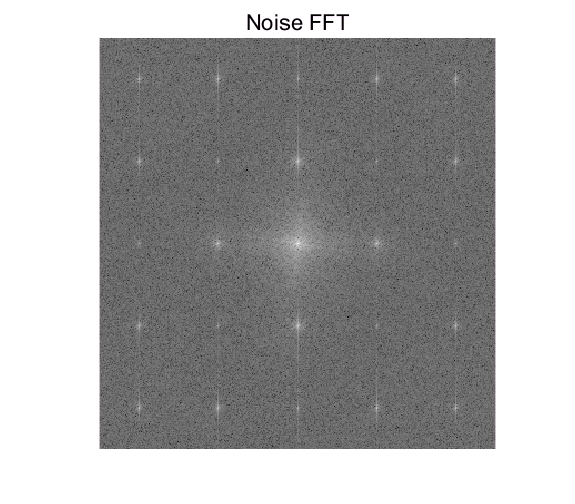

imshow(mat2gray(log(abs(Noise_fft_shift) + 1))); title('Noise FFT');

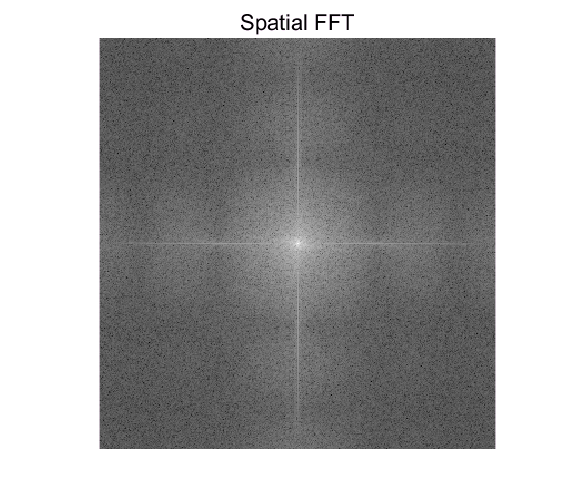

imshow(mat2gray(log(abs(Filter_fft_shift) + 1))); title('Spatial FFT');

%%% FFT %%%

%%% xb %%%
Filter = Noise;
Filter_fft = fft2(double(Filter));
Filter_fft_shift = fftshift(Filter_fft);
H = double(ones(M, N));
row = [37, 111, 185, 259, 333];
col = [36, 107, 178, 249, 320];
dr = 8; dc = 8; dl=0; dcenter=30; n=4;

u=abs([-dr:dr]);
V=repmat(u,dc*2+1,1);
U=V.';
D=sqrt(U.^2+V.^2);
D0=10;

notch = 1-1 ./ (1 + (D ./ D0) .^ (2 * n));

for i=[1 2 3 4 5]
    H(row(i)-dl:row(i)+dl,:)=0;
end
for j=[1 2 3 4 5]
    H(:,col(j)-dl:col(j)+dl)=0;
end

for i = 1:5
    for j = 1:5
        H(row(i) - dr:row(i) + dr, col(j) - dc:col(j) + dc) = notch;
    end
end

H(row(3) - dcenter:row(3) + dcenter, col(3) - dcenter:col(3) + dcenter) = 1;
Filter_fft_shift = Filter_fft_shift .* H;
Filter_fft = ifftshift(Filter_fft_shift);
Filter = real(ifft2(Filter_fft));

mse_Original_Filter = immse(Original, Filter)

mse_Original_Filter = 2.6710e+03

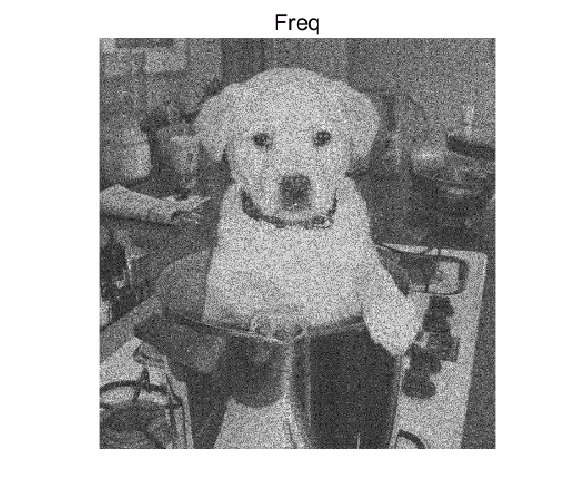

imshow(mat2gray(Filter)); title('Freq');

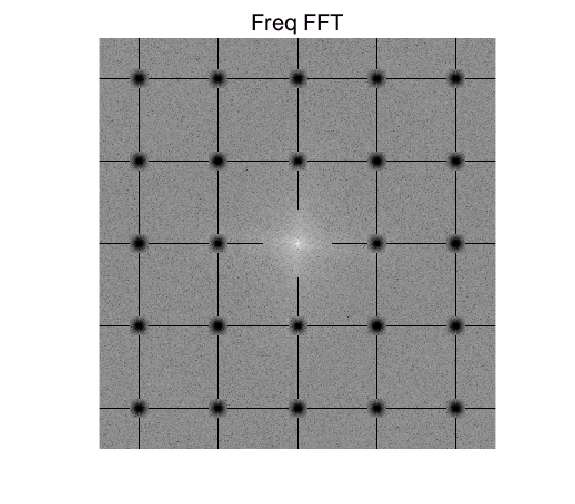

imwrite(mat2gray(Filter),'DogFreq.bmp');
imshow(mat2gray(log(abs(Filter_fft_shift) + 1))); title('Freq FFT');

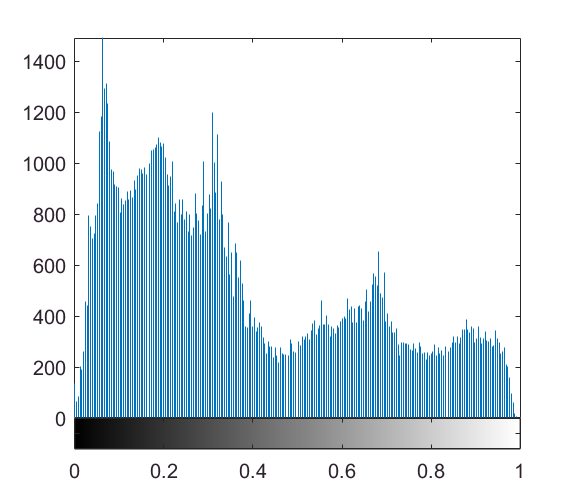

imwrite(mat2gray(log(abs(Filter_fft_shift) + 1)),'DogNotch.bmp');
%%% xb %%%

imhist(mat2gray(Original))

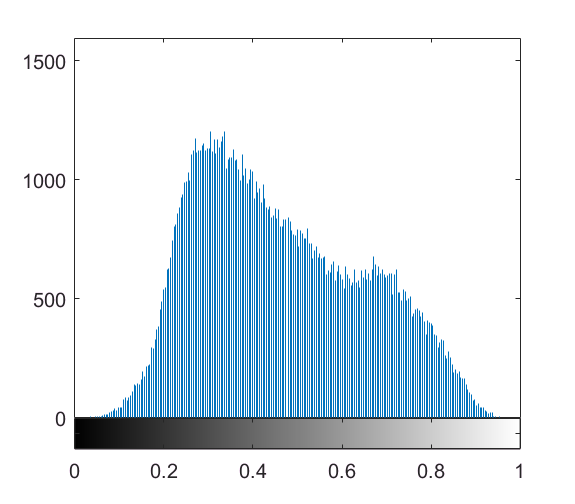

imhist(mat2gray(Filter))


Original_loc=Original_Uint(300:320,200:220);
Filter_loc=Filter(300:320,200:220);
%imshow(Original_loc);
%imshow(Noise_loc);
imhist(Original_loc);

imhist(Noise_loc);

Filter = ordfilt2(Filter,7,ones(5,5),'symmetric');
imshow(mat2gray(Filter)); title('Final');
Filter_fft = fft2(Filter);
Filter_fft_shift = fftshift(Filter_fft);
imshow(mat2gray(log(abs(Filter_fft_shift) + 1))); title('Final FFT');
imwrite(mat2gray(Filter),'DogFinal.bmp');
mse_Original_Filter = immse(Original, double(Filter))

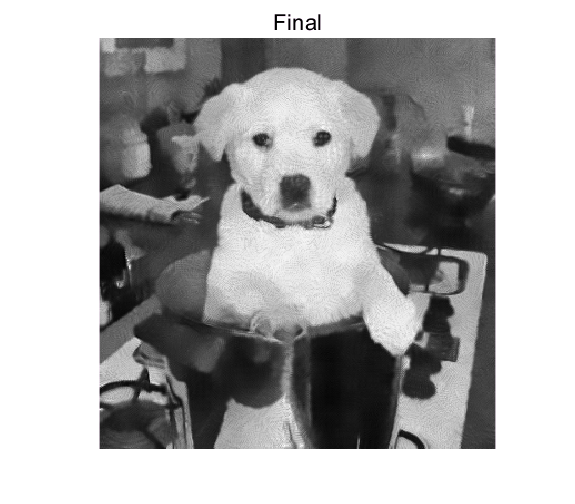

%Filter=RAMF(Filter,3);
%Filter=nlmeans(Filter,2,7,10); 
FilterT = fastNLmeans(Filter,2,7,25);
%Filter = medfilt2(Filter, [5, 5]);
%H = fspecial('average', 5);
%Filter = filter2(H, Filter);
%Filter = ordfilt2(Filter,5,ones(3,3));
%Filter = imgaussfilt(Filter,1.5);
%Filter = histeq(uint8(Filter));
imshow(mat2gray(FilterT)); title('Final');

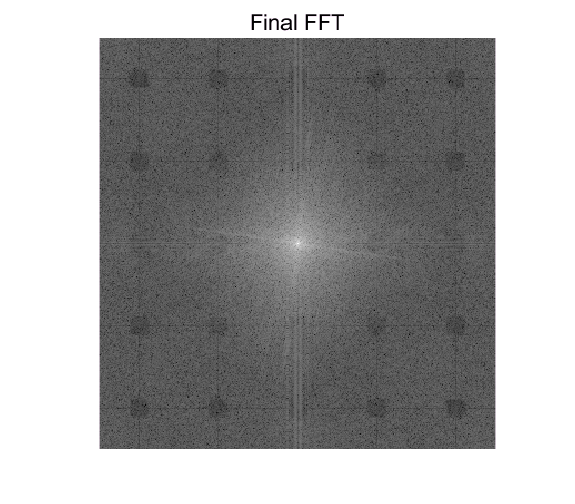

Filter_fft = fft2(FilterT);
Filter_fft_shift = fftshift(Filter_fft);
imshow(mat2gray(log(abs(Filter_fft_shift) + 1))); title('Final FFT');


mse_Original_Filter = immse(Original, double(FilterT))

mse_Original_Filter = 1.8477e+03


imwrite(mat2gray(FilterT),'DogNLM.bmp');

imhist(mat2gray(Original))

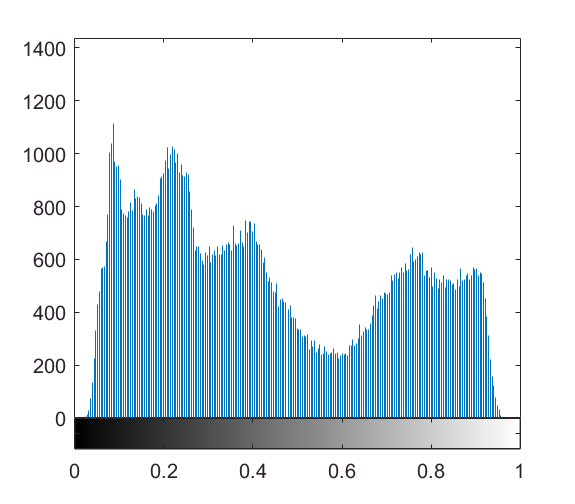

imhist(mat2gray(FilterT))

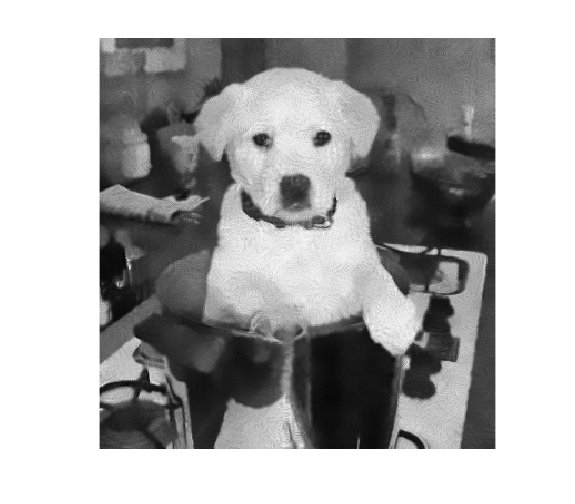

FilterTM=FilterT-40;
imshow(mat2gray(FilterTM))

imwrite(mat2gray(FilterTM),'DogFinal.bmp');
mse_Original_Filter = immse(Original, double(FilterTM))

mse_Original_Filter = 386.1541

Dif=Original-FilterT;